# MATLAB ODE45 Problem 1

## Simulate the system

#### 
$$\dot x = -y+(x^2+y^2)y \\
\dot y = 3x - (x^2+y^2)x$$


The purpose of this assignment is not simply to show that you can get `ode45` to run. The purpose is to demonstrate how the numerically solving an ODE is a useful companion to the qualitative methods we are learning from Strogatz when we're trying to understand the dynamics due to an ODE.

Here is what it looks like using the Slopes app.

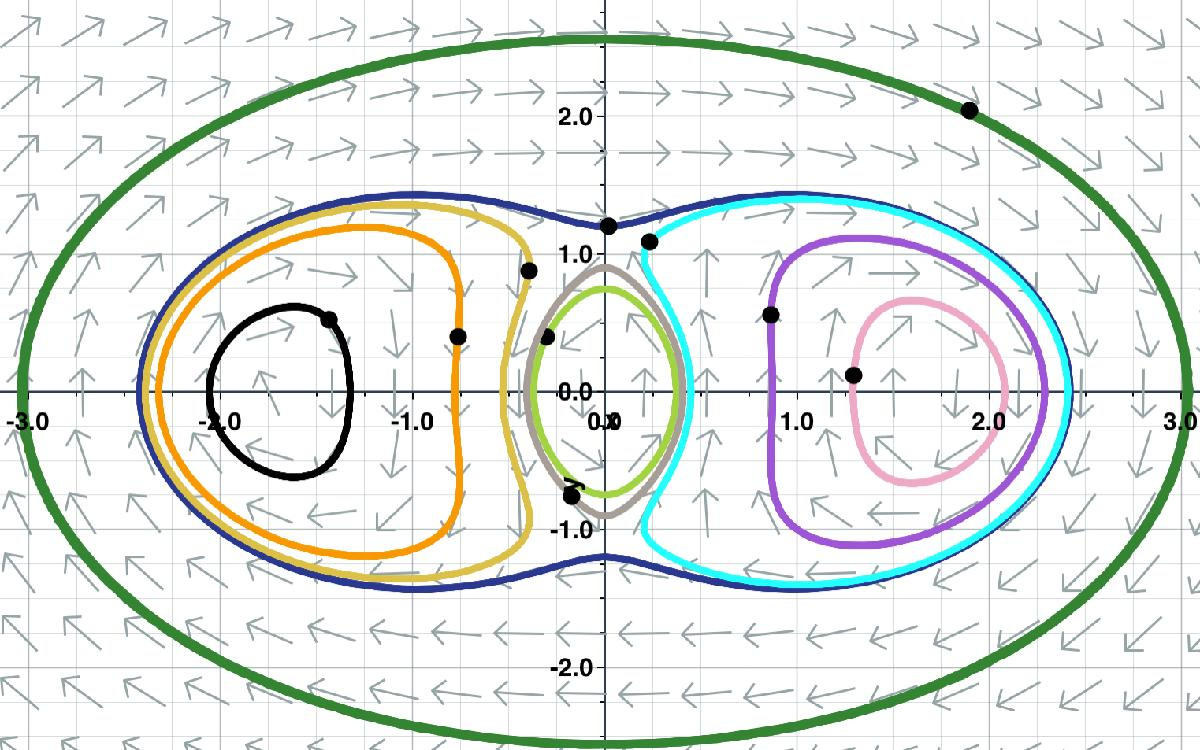

This has five fixed points. $(0,0), (\pm\sqrt{3},0),(0,\pm1)$. The three fixed points on the $x
$-axis are centers and the two fixed points on the $y$-axis are saddles.

This has a conserved energy $H=-\frac32x^2-\frac12y^2+\frac{1}{4}(x^2+y^2)^2$

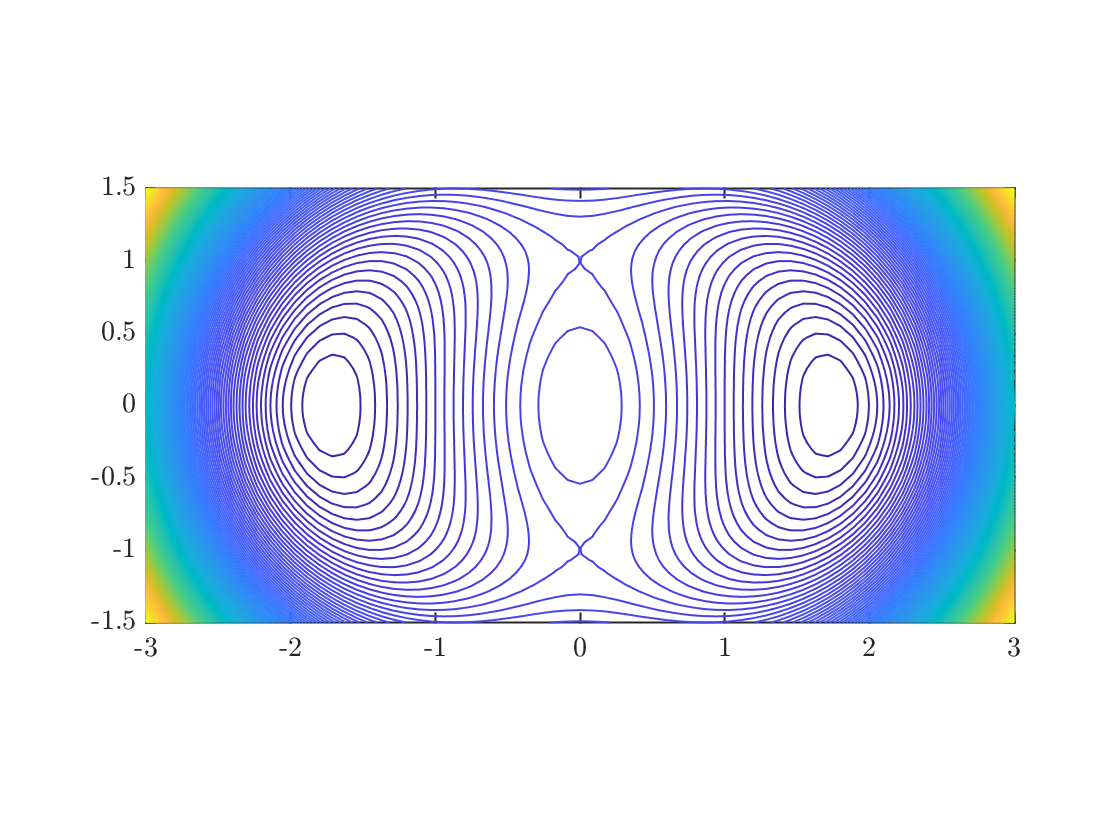

E=@(x,y) -3/2*x.^2-1/2*y.^2+1/4*(x.^2+y.^2).^2;
fcontour(E,[-3 3 -1.5 1.5],'LevelStep',0.125); 
axis equal

That looks a whole lot like the phase plane I plotted, so that's good.

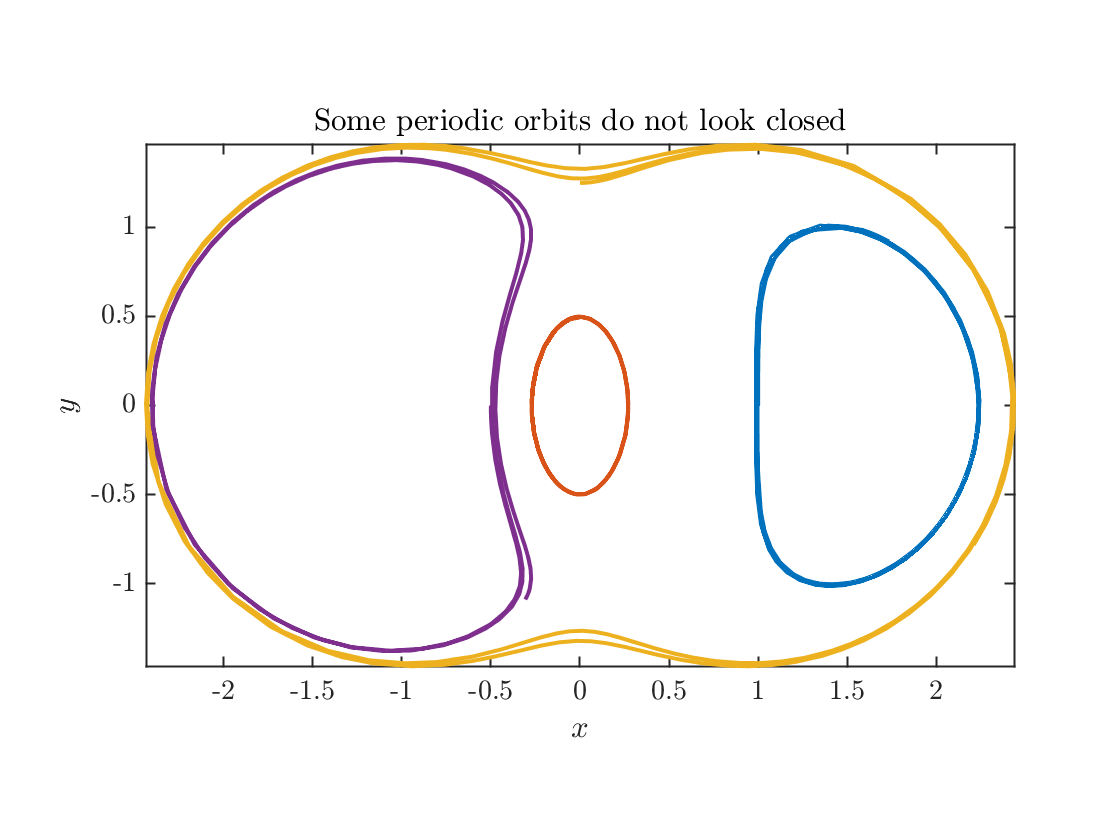

tspan=[0 10];
[t1,y1]=ode45(@firstODE,tspan,[1 0]);
[t2,y2]=ode45(@firstODE,tspan,[0 .5]);
[t3,y3]=ode45(@firstODE,tspan,[0 1.25]);
[t4,y4]=ode45(@firstODE,tspan,[-.5 0]);

plot(y1(:,1),y1(:,2),y2(:,1),y2(:,2),y3(:,1),y3(:,2),y4(:,1),y4(:,2));
axis equal tight
xlabel('$x$');ylabel('$y$');title('Some periodic orbits do not look closed')

The two larger periodic orbits don't seem to be closing on themselves. Since this system conserves an energy, then we should not see spiraling like this. Let's see whether our approximate solutions are conserving energy like they should. Now I calculate the energy and plot it as a function of time.

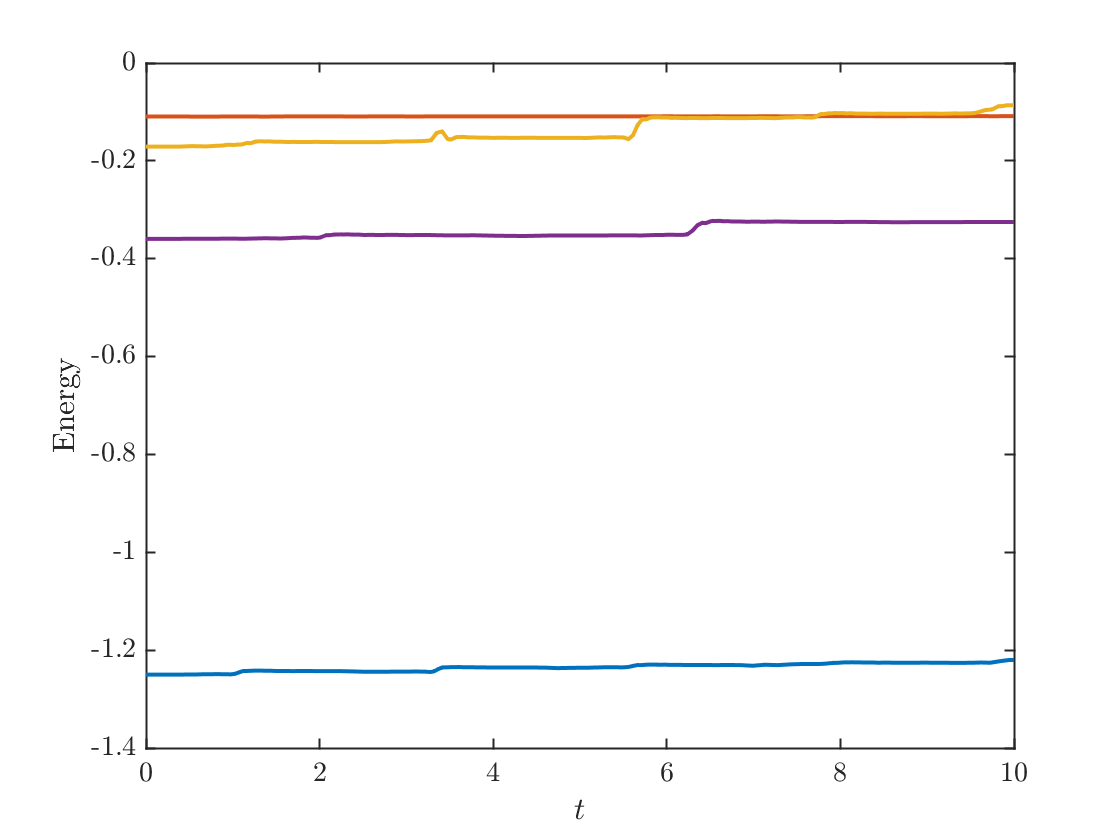

E1=E(y1(:,1),y1(:,2));
E2=E(y2(:,1),y2(:,2));
E3=E(y3(:,1),y3(:,2));
E4=E(y4(:,1),y4(:,2));
figure
plot(t1,E1,t2,E2,t3,E3,t4,E4);
xlabel('$t$');ylabel('Energy')

These numerical approximations don't conserving energy well et all. It appears that the larger the amplitude of the oscillation, the worse the energy conservation properties of the numerical solution.

To fix these problepms I am going to force `ode45` to use smaller time steps by reducing the absolute and relative tolerance that it uses to set the step size. Type `doc odeset` at the MATLAB prompt to see how these work

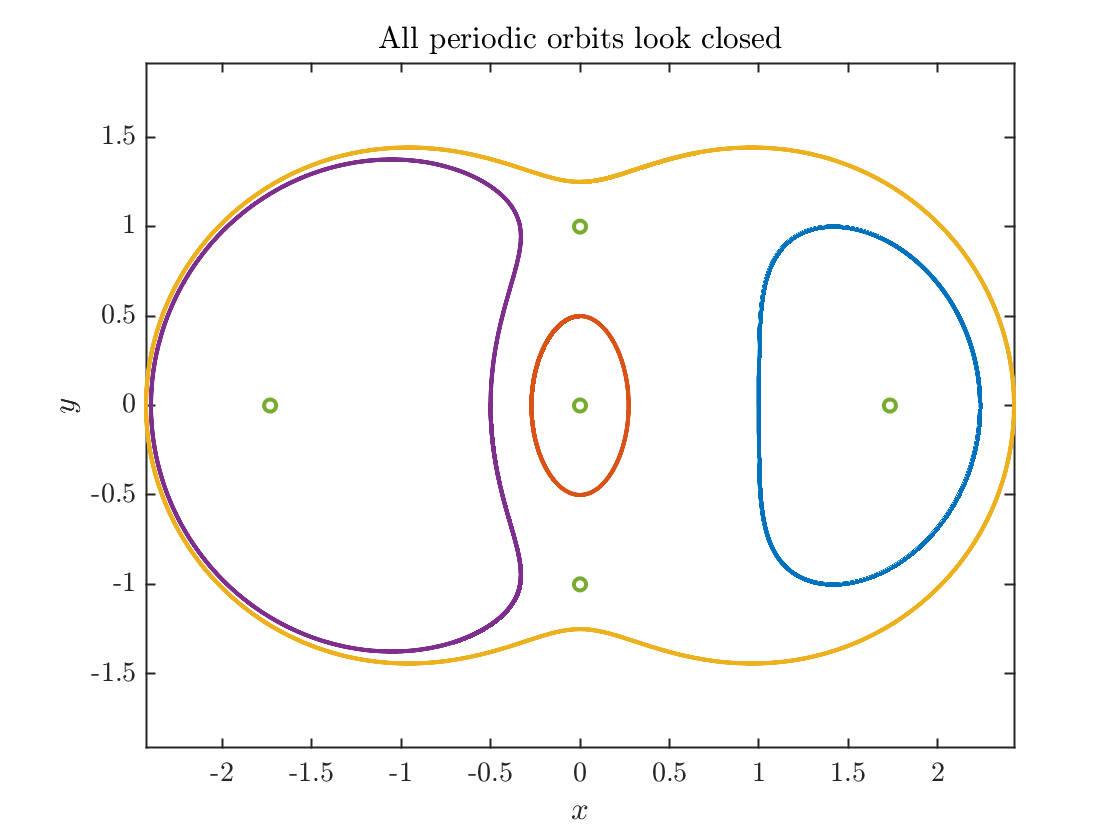

options=odeset('AbsTol',1e-8,'RelTol',1e-8);
[t1,y1]=ode45(@firstODE,tspan,[1 0],options);
[t2,y2]=ode45(@firstODE,tspan,[0 .5],options);
[t3,y3]=ode45(@firstODE,tspan,[0 1.25],options);
[t4,y4]=ode45(@firstODE,tspan,[-.5 0],options);
plot(y1(:,1),y1(:,2),y2(:,1),y2(:,2),y3(:,1),y3(:,2),y4(:,1),y4(:,2))
hold on;
plot([-sqrt(3) 0 sqrt(3) 0 0],[0 0 0 -1 1],'o')
hold off
xlabel('$x$');ylabel('$y$'); axis equal
title('All periodic orbits look closed')

Also see how much better the conservation of energy becomes with these stricter tolerances. Now all the energy plots show horizontal lines. (But if we zoomed in on any one of them, we'd see small variations, since energy conservation is only approximate for numerical solutions.

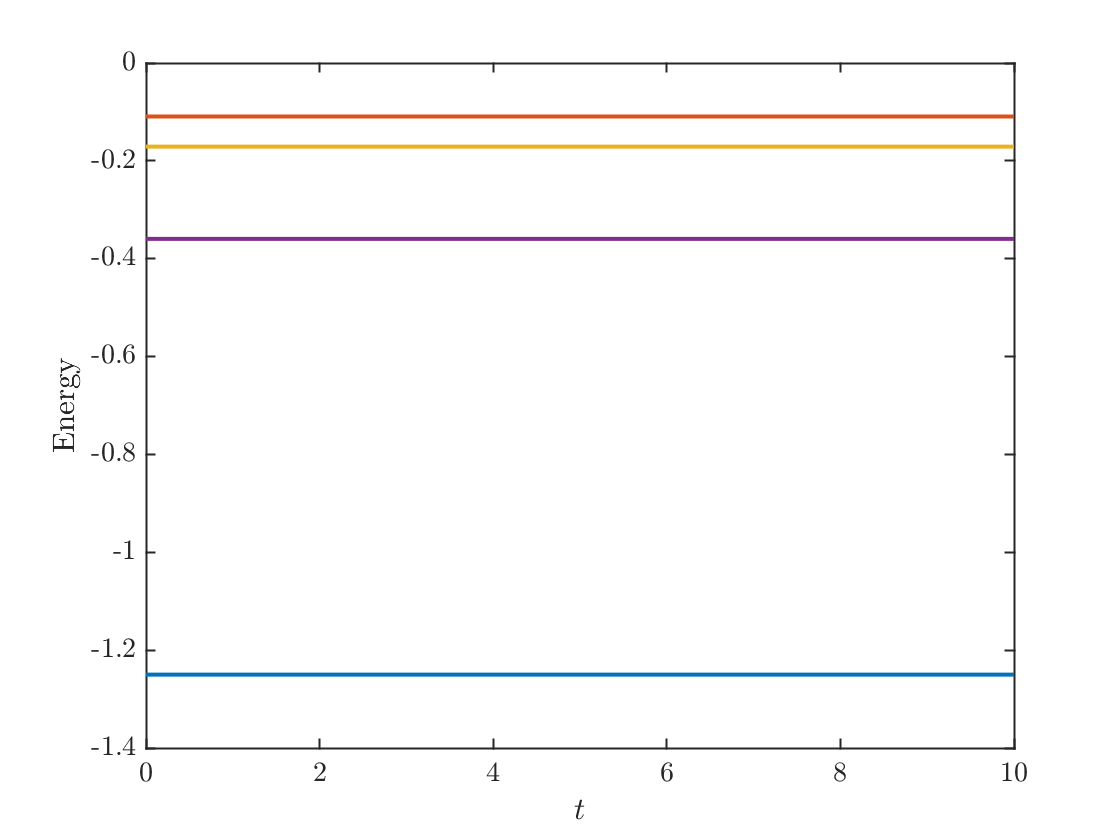

E1=E(y1(:,1),y1(:,2));
E2=E(y2(:,1),y2(:,2));
E3=E(y3(:,1),y3(:,2));
E4=E(y4(:,1),y4(:,2));
plot(t1,E1,t2,E2,t3,E3,t4,E4)
xlabel('$t$');ylabel('Energy')

One thing I notice is that there exist periodic orbits that enclose either one or five fixed points, but each perioci orbit has index=1 as it must.

function dydt=firstODE(~,y)
dydt=zeros(2,1);
r2=y(1)^2+y(2)^2;
dydt(1)=y(2)*(-1+r2);
dydt(2)=y(1)*(3-r2);
end